clc; clear; close all;

syms x1 x2 x3 u;

a1 = 0.02; a2 = 3.64; a3 = 7.21; D0 = 1.2;

fx(x1,x2,x3,u) = [a2*(1-1/x2)*x1-D0*x1;
    a3*(x3/(a1+x3))-a2*(x2-1);
    D0*(1-x3)-x1*x3/(a1+x3)]

$$fx(x1, x2, x3, u) = \left(\begin{array}{c} -\frac{6\,x_{1}}{5}-x_{1}\,\left(\frac{91}{25\,x_{2}}-\frac{91}{25}\right)\\ \frac{721\,x_{3}}{100\,\left(x_{3}+\frac{1}{50}\right)}-\frac{91\,x_{2}}{25}+\frac{91}{25}\\ \frac{6}{5}-\frac{x_{1}\,x_{3}}{x_{3}+\frac{1}{50}}-\frac{6\,x_{3}}{5} \end{array}\right)$$


gx(x1,x2,x3,u) = [-x1; 0; 1-x3]

$$gx(x1, x2, x3, u) = \left(\begin{array}{c} -x_{1}\\ 0\\ 1-x_{3} \end{array}\right)$$


hx(x1,x2,x3,u) = x1

$$hx(x1, x2, x3, u) = x_{1}$$


xdot = fx + gx*u

$$xdot(x1, x2, x3, u) = \left(\begin{array}{c} -\frac{6\,x_{1}}{5}-u\,x_{1}-x_{1}\,\left(\frac{91}{25\,x_{2}}-\frac{91}{25}\right)\\ \frac{721\,x_{3}}{100\,\left(x_{3}+\frac{1}{50}\right)}-\frac{91\,x_{2}}{25}+\frac{91}{25}\\ \frac{6}{5}-u\,\left(x_{3}-1\right)-\frac{x_{1}\,x_{3}}{x_{3}+\frac{1}{50}}-\frac{6\,x_{3}}{5} \end{array}\right)$$


y = hx

$$y(x1, x2, x3, u) = x_{1}$$

# `Part 3:`

EQe = xdot == 0;
solve_EQe = solve(EQe,[x1,x2,x3,u]);
x1e = solve_EQe.x1

$$x1e = \left(\begin{array}{c} 0\\ \frac{147392897}{30699500}\\ 0 \end{array}\right)$$

x2e = solve_EQe.x2

$$x2e = \left(\begin{array}{c} 1\\ \frac{91}{61}\\ \frac{3901}{1326} \end{array}\right)$$

x3e = solve_EQe.x3

$$x3e = \left(\begin{array}{c} 0\\ \frac{156}{23615}\\ 1 \end{array}\right)$$

ue = solve_EQe.u

$$ue = \left(\begin{array}{c} -\frac{6}{5}\\ 0\\ 0 \end{array}\right)$$

# `Part 5:`

A = [diff(xdot,x1) diff(xdot,x2) diff(xdot,x3)]

$$A(x1, x2, x3, u) = \begin{array}{l} \left(\begin{array}{ccc} \frac{61}{25}-\frac{91}{25\,x_{2}}-u & \frac{91\,x_{1}}{25\,{x_{2}}^{2}} & 0\\ 0 & -\frac{91}{25} & \frac{721}{100\,\left(x_{3}+\frac{1}{50}\right)}-\frac{721\,x_{3}}{100\,\sigma_{1}}\\ -\frac{x_{3}}{x_{3}+\frac{1}{50}} & 0 & \frac{x_{1}\,x_{3}}{\sigma_{1}}-\frac{x_{1}}{x_{3}+\frac{1}{50}}-u-\frac{6}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(x_{3}+\frac{1}{50}\right)}^{2} \end{array}$$

B = diff(xdot,u)

$$B(x1, x2, x3, u) = \left(\begin{array}{c} -x_{1}\\ 0\\ 1-x_{3} \end{array}\right)$$

C = [diff(hx,x1) diff(hx,x2) diff(hx,x3)]

$$C(x1, x2, x3, u) = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

D = diff(hx,u)

$$D(x1, x2, x3, u) = 0$$


Alin = A(x1e(2),x2e(2),x3e(2),ue(2))

$$Alin = \left(\begin{array}{ccc} 0 & \frac{548448969737}{69841362500} & 0\\ 0 & -\frac{91}{25} & \frac{156147103}{766526}\\ -\frac{1560}{6283} & 0 & -\frac{22355401}{163358} \end{array}\right)$$

Blin = B(x1e(2),x2e(2),x3e(2),ue(2))

$$Blin = \left(\begin{array}{c} -\frac{147392897}{30699500}\\ 0\\ \frac{23459}{23615} \end{array}\right)$$

Clin = C(x1e(2),x2e(2),x3e(2),ue(2))

$$Clin = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

Dlin = D(x1e(2),x2e(2),x3e(2),ue(2))

$$Dlin = 0$$


xbar = [x1;x2;x3] - [x1e(2);x2e(2);x3e(2)]

$$xbar = \left(\begin{array}{c} x_{1}-\frac{147392897}{30699500}\\ x_{2}-\frac{91}{61}\\ x_{3}-\frac{156}{23615} \end{array}\right)$$

ubar = u - ue(2)

$$ubar = u$$

xbardot = Alin*xbar + Blin*ubar

$$xbardot = \left(\begin{array}{c} \frac{548448969737\,x_{2}}{69841362500}-\frac{147392897\,u}{30699500}-\frac{8990966717}{767487500}\\ \frac{156147103\,x_{3}}{766526}-\frac{91\,x_{2}}{25}+\frac{39135733}{9581575}\\ \frac{23459\,u}{23615}-\frac{1560\,x_{1}}{6283}-\frac{22355401\,x_{3}}{163358}+\frac{329244}{157075} \end{array}\right)$$

ybar = Clin*xbar + Dlin*ubar

$$ybar = x_{1}-\frac{147392897}{30699500}$$

# `Transfer Function`

syms s
G = Clin/(s*eye(3)-Alin) * Blin + Dlin

$$G = \frac{210919088214103}{1300\,\left(102098750\,s^{3}+14343765075\,s^{2}+50858537275\,s+40551649662\right)}-\frac{147392897\,\left(25\,s+91\right)\,\left(163358\,s+22355401\right)}{1227980\,\left(102098750\,s^{3}+14343765075\,s^{2}+50858537275\,s+40551649662\right)}$$

ExpFun = matlabFunction(G);
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
TF = tf(ExpFun(tf('s')))    % closeloop


TF =
 
         -5.005e16 s^5 - 1.406e19 s^4 - 1.021e21 s^3 - 4.698e21 s^2 - 6.96e21 s - 3.323e21
  -----------------------------------------------------------------------------------------------
  1.042e16 s^6 + 2.929e18 s^5 + 2.161e20 s^4 + 1.467e21 s^3 + 3.75e21 s^2 + 4.125e21 s + 1.644e21
 
Continuous-time transfer function.



Gs = TF/(1-TF)              % openloop


Gs =
 
                                                                                                             
  -5.217e32 s^11 - 2.932e35 s^10 - 6.265e37 s^9 - 6.152e39 s^8 - 2.553e41 s^7 - 2.587e42 s^6 - 1.229e43 s^5  
                                                                                                             
                                         - 3.278e43 s^4 - 5.203e43 s^3 - 4.889e43 s^2 - 2.515e43 s - 5.464e42
                                                                                                             
  -----------------------------------------------------------------------------------------------------------
                                                                                                             
  1.087e32 s^12 + 6.159e34 s^11 + 1.338e37 s^10 + 1.359e39 s^9 + 6.154e40 s^8 + 9.116e41 s^7 + 6.385e42 s^6  
                                                                                                             
  

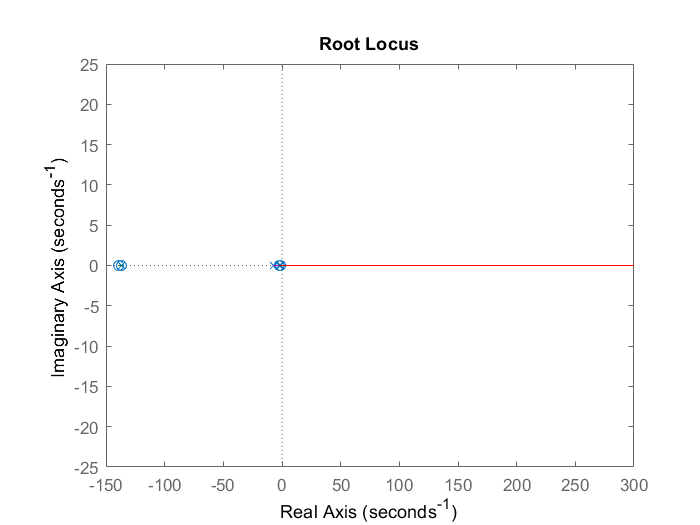

rlocus(Gs)

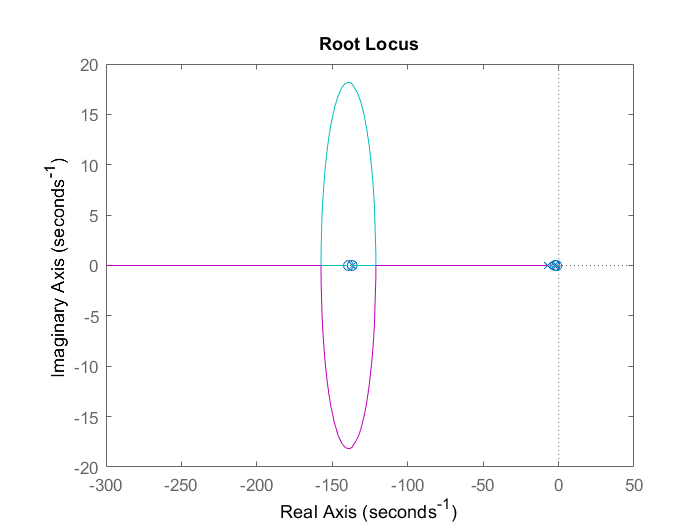

rlocus(-Gs)


k = -10;
Gs = k*Gs;
TF = Gs/(1+Gs);

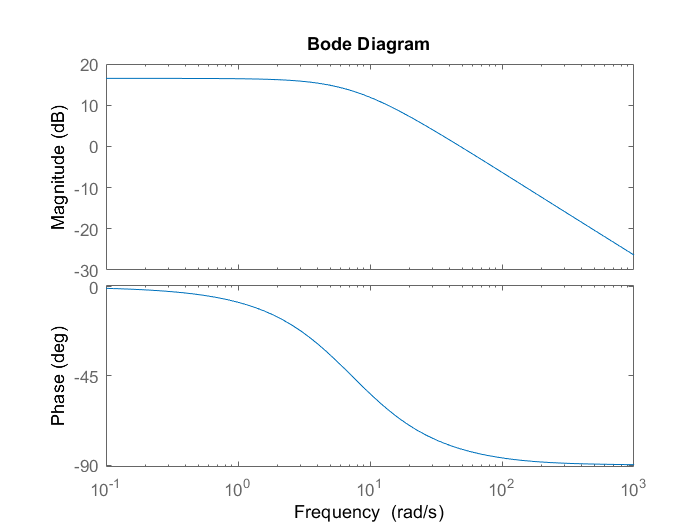

bode(Gs)

G1 = 100*Gs


G1 =
 
                                                                                                             
  5.217e35 s^11 + 2.932e38 s^10 + 6.265e40 s^9 + 6.152e42 s^8 + 2.553e44 s^7 + 2.587e45 s^6 + 1.229e46 s^5   
                                                                                                             
                                         + 3.278e46 s^4 + 5.203e46 s^3 + 4.889e46 s^2 + 2.515e46 s + 5.464e45
                                                                                                             
  -----------------------------------------------------------------------------------------------------------
                                                                                                             
  1.087e32 s^12 + 6.159e34 s^11 + 1.338e37 s^10 + 1.359e39 s^9 + 6.154e40 s^8 + 9.116e41 s^7 + 6.385e42 s^6  
                                                                                                             
  

syms b
eq = -20*log10(b) + 20*log10(abs(evalfr(G1,1j*10))) == 0;
beta = vpasolve(eq,b)

$$beta = 394.6861350372777001411769627273$$


s = tf('s');
Cs = 100 * (s+1)/(400*s+1)


Cs =
 
  100 s + 100
  -----------
   400 s + 1
 
Continuous-time transfer function.



GCs = Gs*Cs


GCs =
 
                                                                                                             
  5.217e35 s^12 + 2.937e38 s^11 + 6.294e40 s^10 + 6.215e42 s^9 + 2.615e44 s^8 + 2.842e45 s^7 + 1.488e46 s^6  
                                                                                                             
                          + 4.507e46 s^5 + 8.481e46 s^4 + 1.009e47 s^3 + 7.404e46 s^2 + 3.061e46 s + 5.464e45
                                                                                                             
  -----------------------------------------------------------------------------------------------------------
                                                                                                             
  4.347e34 s^13 + 2.463e37 s^12 + 5.351e39 s^11 + 5.437e41 s^10 + 2.462e43 s^9 + 3.647e44 s^8 + 2.555e45 s^7 
                                                                                                             
 

TFc = GCs/(1+GCs)


TFc =
 
                                                                                                                
  2.268e70 s^25 + 2.562e73 s^24 + 1.276e76 s^23 + 3.676e78 s^22 + 6.738e80 s^21 + 8.147e82 s^20 + 6.507e84 s^19 
                                                                                                                
          + 3.345e86 s^18 + 1.049e88 s^17 + 1.902e89 s^16 + 2.16e90 s^15 + 1.662e91 s^14 + 9.161e91 s^13        
                                                                                                                
          + 3.753e92 s^12 + 1.172e93 s^11 + 2.831e93 s^10 + 5.338e93 s^9 + 7.873e93 s^8 + 9.052e93 s^7          
                                                                                                                
            + 8.027e93 s^6 + 5.383e93 s^5 + 2.64e93 s^4 + 8.935e92 s^3 + 1.868e92 s^2 + 1.831e91 s + 4.463e88   
                                                                                       

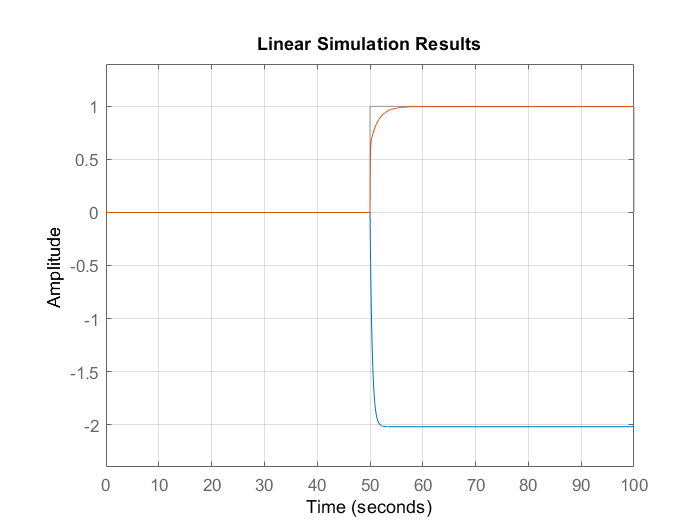

[x,t] = gensig('square',100,100,0.01);
TForiginal = (-Gs/10)/(1 - Gs/10);
lsim(TForiginal,TFc,x,t)
set(gca,'xtick', 0 : 10 : 100, 'xlim', [0,100]);
set(gca,'ytick', -3 : 0.5 : 2, 'ylim', [-2.4,1.4]);
grid on;